# Chapter 7 : Optimum filters

## Ex7.3 : FIR Wiener - Noise Cancellation (7.2.6)

The noise cancellation problem is described by the following figure:

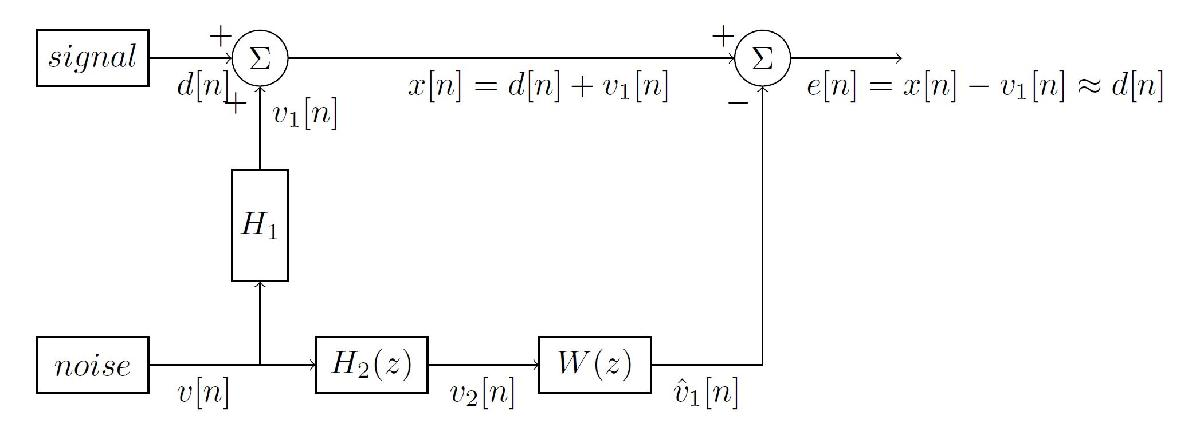

Suppose the desired signal d[n] is given by :


$$d\left\lbrack n\right\rbrack =\sin \left(n\omega_0 +\phi \;\right)$$


with $\omega_0 = 0.05\pi$and the related noise sequence$v_1[n]$ and $v_2[n]$ are AR(1) processes driven by the same noise signal $v[n]$.


$$v_1 \left\lbrack n\right\rbrack =0\ldotp 8v_1 \left\lbrack n-1\right\rbrack +v\left\lbrack n\right\rbrack$$



$$H_1 \left(z\right)=\frac{1}{1-0\ldotp 8z^{-1} }$$



$$v_2 \left\lbrack n\right\rbrack =-0\ldotp 6v_2 \left\lbrack n-1\right\rbrack +v\left\lbrack n\right\rbrack$$



$$H_2 \left(z\right)=\frac{1}{1+0\ldotp 6z^{-1} }$$


Where v[n] is zero-mean, unit variance white noise that is clearly uncorrelated with d[n].

Goal is to design a FIR Wiener filter of orders 6 and 12 to remove the noise.

## Signals creation

### Parameters

## Signal generation

Based on the previous parameters, the signals are generated.

## Wiener solving

### Filter design

The Wiener-Hopf equations for the noise cancellation described by figure are given by :


$${\mathit{\mathbf{R}}}_{v_2 ,v_2 } \mathit{\mathbf{w}}={\mathit{\mathbf{r}}}_{v_1 ,v_2 }$$


As we assume that the noise $v_2[n]$ is uncorrelated with $d[n]$:


$$r_{v_1 ,v_2 } \left\lbrack k\right\rbrack =E\left\lbrace v_1 \left\lbrack n\right\rbrack {v_2 }^* \left\lbrack n-k\right\rbrack \right\rbrace =E\left\lbrace \left\lbrack x\left\lbrack n\right\rbrack -d\left\lbrack n\right\rbrack \right\rbrack {v_2 }^* \left\lbrack n-k\right\rbrack \right\rbrace =E\left\lbrace x\left\lbrack n\right\rbrack v_2 \left\lbrack n-k\right\rbrack \right\rbrace$$


Then, the Wiener-Hopf equations become:


$${\mathit{\mathbf{R}}}_{v_2 ,v_2 } \mathit{\mathbf{w}}={\mathit{\mathbf{r}}}_{x,v_2 }$$


And the solution is:


$$\mathit{\mathbf{w}}={\mathit{\mathbf{R}}}_{v_2 ,v_2 }^{-1} {\mathit{\mathbf{r}}}_{x,v_2 }$$


The different correlation and cross-correlation are (for two different orders):

The Wiener coefficients obtained are:

### filtering

Estimate the noise v1 based on v2 and the Wiener filter designed

Finally, the estimated noise can be removed from the measured signal.

And the error on the signal reconstruction can be computed: